clc% clean
close all% close all windows
clear all% clear of memory all variable

## Read recorded holograms

% Lines to add folders for reading images and/or functions
% EAFIT computer
addpath('C:\Users\Alan Schneider\OneDrive - University of Massachusetts Dartmouth\PhD\CONFERENCES\SPIE OPTICS AND PHOTONICS\ALAN POSTER\MATLAB\')

% addpath('C:\Users\racastaneq\Documents\MEGA\MEGAsync\RACQ\Universities\05 EAFIT\Research projects\2023\SI-SOFI\GitHub versions\Matlab\')

% Load the hologram
name1 =  "C:\Users\Alan Schneider\OneDrive - University of Massachusetts Dartmouth\ALAN\SUMMER PROJECT\CODES\ALAN CODE\OBLIQUE ILLUMINATION\struct IMG\holo1_angle60.bmp" 

name1 = "C:\Users\Alan Schneider\OneDrive - University of Massachusetts Dartmouth\ALAN\SUMMER PROJECT\CODES\ALAN CODE\OBLIQUE ILLUMINATION\struct IMG\holo1_angle60.bmp"

name2 =  "C:\Users\Alan Schneider\OneDrive - University of Massachusetts Dartmouth\ALAN\SUMMER PROJECT\CODES\ALAN CODE\OBLIQUE ILLUMINATION\struct IMG\holo2_angle60.bmp"; 
[f,p] = uigetfile("*.bmp","Select holograms",MultiSelect="on");
names = strcat(p,f)

names = 1×6 cell array
    {'C:\Users\Alan Schneider\OneDrive - University of Massachusetts Dartmouth\ALAN\SUMMER PROJECT\CODES\ALAN CODE\OBLIQUE ILLUMINATION\struct IMG\holo1_angle0.bmp'}    {'C:\Users\Alan Schneider\OneDrive - University of Massachusetts Dartmouth\ALAN\SUMMER PROJECT\CODES\ALAN CODE\OBLIQUE ILLUMINATION\struct IMG\holo1_angle60.bmp'}    {'C:\Users\Alan Schneider\OneDrive - University of Massachusetts Dartmouth\ALAN\SUMMER PROJECT\CODES\ALAN CODE\OBLIQUE ILLUMINATION\struct IMG\holo1_angle120.bmp'}    {'C:\Users\Alan Schneider\OneDrive - University of Massachusetts Dartmouth\ALAN\SUMMER PROJECT\CODES\ALAN CODE\OBLIQUE ILLUMINATION\struct IMG\holo2_angle0.bmp'}    {'C:\Users\Alan Schneider\OneDrive - University of Massachusetts Dartmouth\ALAN\SUMMER PROJECT\CODES\ALAN CODE\OBLIQUE ILLUMINATION\struct IMG\holo2_angle60.bmp'}    {'C:\Users\Alan Schneider\OneDrive - University of Massachusetts Dartmouth\ALAN\SUMMER PROJECT\CODES\ALAN CODE\OBLIQUE ILLUMINATION\struct IMG\h

[h1,M,N,m,n] = function_heuristic.holo_read(name1);
[h2,M,N,m,n] = function_heuristic.holo_read(name2);

for i = 1:6
    % Read the holograms in the loop
    [h{i}, M, N, m, n] = function_heuristic.holo_read(names{i});
end

%Input parameters to record the holograms
lambda = 0.532;   % Source's wavelength in microns
k = 2*pi/lambda;  % Wavenumber in microns
dxy = 4.65;       % Pitch in X and Y direction in microns
fx_0 = M/2;
fy_0 = N/2;

% Fourier transform of the holograms
H1 = fftshift(fft2(fftshift(h{1})));
H2 = fftshift(fft2(fftshift(h{2})));

% Display the Fourier spectrum of the first hologram
figure; colormap gray; imagesc(abs(H1).^0.1); axis image;

holo(:,:,1) = h1;
holo(:,:,2) = h2;
[holo_filter,holo_FT,fx_max,fy_max] = function_heuristic.spatialFilter_SIDHM(holo,M,N,'Not');
%figure; colormap gray; imagesc(abs(holo_filter).^0.1); axis image;


% minimization particleswarm
repeat_minimization = true;
while repeat_minimization
    % Minimization particleswarm
    % Blind demodulation to recover the two shifted object spectrum individually without prior knowledge of the phase in the SI pattern
    test_theta = randi([0 360])*pi/180;
    lb = 0;
    ub = 360*pi/180;

    options = optimoptions('particleswarm', 'Display', 'off', 'SwarmSize', 4, ...
        'MaxIterations', 500, 'FunctionTolerance', 1e-8);
    cf_particleswarm = @(test_theta) function_heuristic.costFunction_SIDHM(test_theta, holo_FT, fx_max, fy_max);

    tic
    [theta, cf_particleswarm_val] = particleswarm(@(params) function_heuristic.costFunction_SIDHM(params, holo_FT, fx_max, fy_max), 1, lb, ub, options);
    toc

    fprintf('theta 1: %f\n', theta);

    [Gdemod] = function_heuristic.demComp2SIDHM(theta, holo_FT);
    Gplus_demod = Gdemod(:,: ,1);
    figure, imagesc(log(abs(Gplus_demod).^2))
 
    % Ask the user if they want to repeat
    answer = input('Do you want to repeat the minimization? (y/n): ', 's');
    if lower(answer) ~= 'y'
        repeat_minimization = false;
    end
end

Elapsed time is 12.501782 seconds.


theta 1: 0.300001


close all

gplus = fftshift(ifft2(fftshift(Gplus_demod)));
gplus = gplus * -1;
[circ, ref_gplus] = function_heuristic.phase_rec(gplus, dxy, dxy, lambda);
gplus1 = gplus .* ref_gplus;
Gplus1 = FT(gplus1);

% Find max in A_before
[~, idx_before] = max(log(abs(Gplus_demod(:)).^2));
[row_before, col_before] = ind2sub(size(Gplus_demod), idx_before);

% Find max in A_after
[~, idx_after] = (max(log(abs(Gplus1(:)).^2)));
[row_after, col_after] = ind2sub(size(Gplus1), idx_after);

% Calculate displacement
delta_row = row_after - row_before;
delta_col = col_after - col_before;
circ1 = circshift(circ, [delta_row, delta_col]);

FT_centrada = FT(gplus1).*circ1;
Centered_complex_field = IFT(FT_centrada);
zero_phase = (Centered_complex_field);

figure, imagesc((abs(FT(zero_phase)).^.2)), colormap gray

% Blind demodulation to recover the two shifted object spectrum individually without prior knowledge of the phase in the SI pattern
repeat_minimization = true;

while repeat_minimization
    test_theta = randi([0 360])*pi/180;
    cf_particleswarm = function_heuristic.costFunction_SIDHMII(test_theta,holo_FT,fx_max,fy_max);

    tic
    [theta, cf_particleswarm] = particleswarm(@(params) function_heuristic.costFunction_SIDHMII(params,holo_FT,fx_max,fy_max), 1, lb, ub, options);
    toc

    fprintf('theta 2: %f\n', theta);

    [Gdemod] =  function_heuristic.demComp2SIDHM(theta, holo_FT);
    Gminus_demod = Gdemod(:,:,2);
    figure, imagesc(log(abs(Gminus_demod).^2))

    % Ask the user if they want to repeat
    answer = input('Do you want to repeat the minimization? (y/n): ', 's');
    if lower(answer) ~= 'y'
        repeat_minimization = false;
    end
end

Elapsed time is 13.210466 seconds.


theta 2: 1.880020


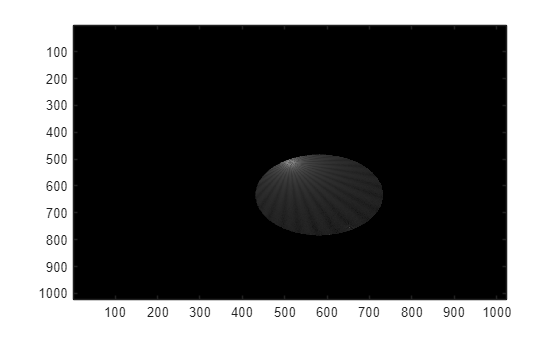

close all

gminus = fftshift(ifft2(fftshift(Gminus_demod)));
[circ, ref_minus] = function_heuristic.phase_rec(gminus, dxy, dxy, lambda);
gminus1 = gminus .* ref_minus;
Gminus1 = FT(gminus1);
% Find max in A_before
[~, idx_before] = max(log(abs(Gminus_demod(:)).^2));
[row_before, col_before] = ind2sub(size(Gminus_demod), idx_before);

% Find max in A_after
[~, idx_after] = (max(log(abs(Gminus1(:)).^2)));
[row_after, col_after] = ind2sub(size(Gminus1), idx_after);

% Calculate displacement
delta_row = row_after - row_before;
delta_col = col_after - col_before;
circ2 = circshift(circ, [delta_row, delta_col]);

FT_centrada2 = FT(gminus1).*circ2;
Centered_complex_field2 = IFT(FT_centrada2);
zero_phase2 = (Centered_complex_field2);

% figure, imagesc(angle(zero_phase2))
figure, imagesc((abs(FT(zero_phase2)).^.2)), colormap gray

Lines to implement the spatial filter using a circular mask

holo(:,:,1) = h1;
holo(:,:,2) = h2;
[holo_filter,holo_FT,fx_max,fy_max] = function_heuristic.spatialFilter_SIDHM(holo,M,N,'Not');


% minimization particleswarm
repeat_minimization = true;
while repeat_minimization
    % Minimization particleswarm
    % Blind demodulation to recover the two shifted object spectrum individually without prior knowledge of the phase in the SI pattern
    test_theta = randi([0 360])*pi/180;
    lb = 0;
    ub = 360*pi/180;

    options = optimoptions('particleswarm', 'Display', 'off', 'SwarmSize', 4, ...
        'MaxIterations', 500, 'FunctionTolerance', 1e-8);
    cf_particleswarm = @(test_theta) function_heuristic.costFunction_SIDHM(test_theta, holo_FT, fx_max, fy_max);

    tic
    [theta, cf_particleswarm_val] = particleswarm(@(params) function_heuristic.costFunction_SIDHM(params, holo_FT, fx_max, fy_max), 1, lb, ub, options);
    toc

    fprintf('theta 1: %f\n', theta);

    [Gdemod] = function_heuristic.demComp2SIDHM(theta, holo_FT);
    Gplus_demod = Gdemod(:,: ,1);
    figure, imagesc(log(abs(Gplus_demod).^2))
 
    % Ask the user if they want to repeat
    answer = input('Do you want to repeat the minimization? (y/n): ', 's');
    if lower(answer) ~= 'y'
        repeat_minimization = false;
    end
end

Elapsed time is 15.620781 seconds.


theta 1: 0.300001


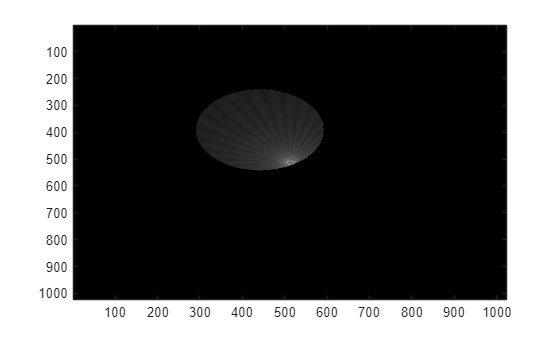

close all

gplus = fftshift(ifft2(fftshift(Gplus_demod)));
gplus = gplus * -1;
[circ, ref_gplus] = function_heuristic.phase_rec(gplus, dxy, dxy, lambda);
gplus1 = gplus .* ref_gplus;
Gplus1 = FT(gplus1);

% Find max in A_before
[~, idx_before] = max(log(abs(Gplus_demod(:)).^2));
[row_before, col_before] = ind2sub(size(Gplus_demod), idx_before);

% Find max in A_after
[~, idx_after] = (max(log(abs(Gplus1(:)).^2)));
[row_after, col_after] = ind2sub(size(Gplus1), idx_after);

% Calculate displacement
delta_row = row_after - row_before;
delta_col = col_after - col_before;
circ1 = circshift(circ, [delta_row, delta_col]);

FT_centrada = FT(gplus1).*circ1;
Centered_complex_field = IFT(FT_centrada);
zero_phase = (Centered_complex_field);

figure, imagesc((abs(FT(zero_phase)).^.2)), colormap gray

Elapsed time is 19.935457 seconds.


theta 2: 1.880020


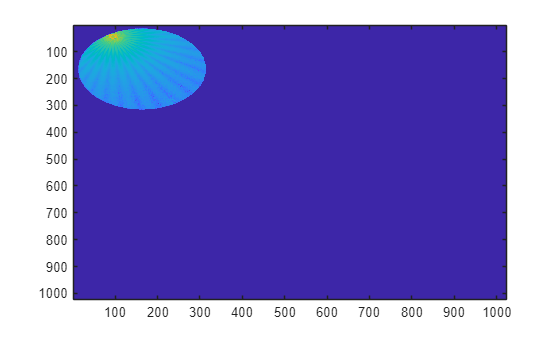


% Blind demodulation to recover the two shifted object spectrum individually without prior knowledge of the phase in the SI pattern
repeat_minimization = true;

while repeat_minimization
    test_theta = randi([0 360])*pi/180;
    cf_particleswarm = function_heuristic.costFunction_SIDHMII(test_theta,holo_FT,fx_max,fy_max);

    tic
    [theta, cf_particleswarm] = particleswarm(@(params) function_heuristic.costFunction_SIDHMII(params,holo_FT,fx_max,fy_max), 1, lb, ub, options);
    toc

    fprintf('theta 2: %f\n', theta);

    [Gdemod] =  function_heuristic.demComp2SIDHM(theta, holo_FT);
    Gminus_demod = Gdemod(:,:,2);
    figure, imagesc(log(abs(Gminus_demod).^2))

    % Ask the user if they want to repeat
    answer = input('Do you want to repeat the minimization? (y/n): ', 's');
    if lower(answer) ~= 'y'
        repeat_minimization = false;
    end
end

close all

gminus = fftshift(ifft2(fftshift(Gminus_demod)));
[circ, ref_minus] = function_heuristic.phase_rec(gminus, dxy, dxy, lambda);
gminus1 = gminus .* ref_minus;
Gminus1 = FT(gminus1);
% Find max in A_before
[~, idx_before] = max(log(abs(Gminus_demod(:)).^2));
[row_before, col_before] = ind2sub(size(Gminus_demod), idx_before);

% Find max in A_after
[~, idx_after] = (max(log(abs(Gminus1(:)).^2)));
[row_after, col_after] = ind2sub(size(Gminus1), idx_after);

% Calculate displacement
delta_row = row_after - row_before;
delta_col = col_after - col_before;
circ2 = circshift(circ, [delta_row, delta_col]);

FT_centrada2 = FT(gminus1).*circ2;
Centered_complex_field2 = IFT(FT_centrada2);
zero_phase2 = (Centered_complex_field2);

% figure, imagesc(angle(zero_phase2))
figure, imagesc((abs(FT(zero_phase2)).^.2)), colormap gray

## Minimization particleswarm

Blind demodulation to recover the two shifted object spectrum individually without prior knowledge of the phase in the SI pattern